# Fuzzy Control Moon Landing Challenge

This is a simplified moon landing simulation.

Parameters of the system:

M       = 7.346e22;         % mass of moon [kg]
R       = 3474e3/2;         % radius of moon [m]
gamma   = 6.6743e-11;       % gravitational constant
m0_sol  = 2e3;              % mass of the lunar spacecraft without fuel [kg]
h0      = 10e3;             % initial altitude above ground level [m]
Pmax    = 45e3;             % maximum thrust of descent propulsion system [N]
mdmax   = Pmax/2500;        % fuel rate at max thrust Pmax/deltav_fuel
m0_fuel = 8e3;              % initial fuel mass [kg]
m0      = m0_sol + m0_fuel; % total initial mass of spacecraft

Calculate the initial and final gravitational force with initial mass:

F0      = gamma * M * m0 / (h0 + R)^2

F0 = 1.6065e+04

Ff      = gamma * M * m0 / R^2

Ff = 1.6250e+04

Calculate the equilibrium thrust settings for full and 80% full vehicle:

P_eq_0  = Ff/Pmax*100

P_eq_0 = 36.1114

Ff_80   = gamma * M * (m0_sol+0.8*m0_fuel) / R^2;
P_eq_80 = Ff_80/Pmax*100

P_eq_80 = 30.3336

## Simplified State Space Model for a Classic Approach

Equations of motion read:


$$\dot{v} = 1/m_0 (F_{thrust}-F_g)\\
\dot{h} = v$$


Gravitational force Fg is now assumed to be constant and the thrust is proportional to an input signal u [0,100%]:


$$F_{thrust} = \frac{P_{max}}{100} \cdot u$$


hence with x1=h and x2=v:


$$\dot{x} = \left[\begin{array}{l}
x_2\\
1/m_0 \cdot (P_{max}/100\cdot u - F_f)
\end{array}
\right]$$


Let $u_0
$ be the thrust equal to Fg and $u = u_0+\Delta u
$. Then the state space model reads


$$\dot x = \left[ \begin{array}{ll}
0 & 1 \\
0 & 0
\end{array}
\right] \cdot x + 
\left[ \begin{array}{c}
0  \\
\frac{P_{max}}{100\cdot m_0} 
\end{array}
\right] \cdot \Delta u$$


Output equation:


$$y=[1~~0]\cdot x$$


A state space controller u=-K*x with appropriate negative real poles to avoid crash:

A = [0,1;0,0];
B = [0; Pmax/(100*m0)];
C = [1, 0];
D = 0;
sys = ss(A,B,C,D);
poles = [-1/20-1/40*1i; -1/20+1/40*1i];
K = place(A,B,poles)

K =     0.0694    2.2222


V = inv(C*inv(B*K-A)*B)

V = 0.0694

t = [0,150,200,250,500]

t =      0   150   200   250   500


hs= [10e3, 10e2, 200, 0, 0];

## Fuzzy Approach ...

The first approach is Fuzzy Control straight forward. We use altitude and velocity as input variables for a FIS that creates thrust as output. We use the expertise we gained by manually trying to land the spacecraft by observing altitude and velocity to set the thrust.

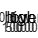

% create single comprehensive fis:
fis_full    = sugfis("Name","lunar_full");
fis_full    = addInput(fis_full,[0 1e4],"Name","altitude");
fis_full    = addInput(fis_full,[-120, +20],"Name","velocity");
fis_full    = addOutput(fis_full,[0, 100], "Name", "thrust");
% define input membership functions for 1st input:
fis_full    = addMF(fis_full,"altitude","trimf",[-300, 0, 300],"Name","very low");
fis_full    = addMF(fis_full,"altitude","trimf",[0, 1500, 3000],"Name","low");
fis_full    = addMF(fis_full,"altitude","linsmf",[1500, 3000],"Name","high");
figure(1); plotmf(fis_full,"input",1)

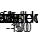

% define input membership functions for 2nd input:
fis_full    = addMF(fis_full,"velocity","linzmf",[-80,-60],"Name","very fast down");
fis_full    = addMF(fis_full,"velocity","trapmf",[-80,-70,-30,-20],"Name","fast down");
fis_full    = addMF(fis_full,"velocity","trapmf",[-30,-20,-10,-5],"Name","moderate down");
fis_full    = addMF(fis_full,"velocity","trapmf",[-10,-5,-2,0],"Name","slowly down");
fis_full    = addMF(fis_full,"velocity","linsmf",[0,5],"Name","upwards");
figure(2); plotmf(fis_full,"input",2)

fis_full = addMF(fis_full,"thrust","constant",0 ,"Name","off");
fis_full = addMF(fis_full,"thrust","constant",25 ,"Name","low");
fis_full = addMF(fis_full,"thrust","constant",31 ,"Name","medium");
fis_full = addMF(fis_full,"thrust","constant",60 ,"Name","high");
fis_full = addMF(fis_full,"thrust","constant",100 ,"Name","maximum");
% Add rules:
% Column 1 — Index of membership function for first input h
% Column 2 — Index of membership function for second input v
% Column 3 — Index of membership function for output P
% Column 4 — Rule weight (from 0 to 1)
% Column 5 — Fuzzy operator (1 for AND, 2 for OR)
rules = ...
    [1, 4, 3, 1.0, 1; ...   % IF h=very low AND v=slowly down THEN P=medium
     1, 3, 4, 1.0, 1; ...   % IF h=very low AND v=moderate down THEN P=high
     1, 2, 4, 1.0, 1; ...   % IF h=very low AND v=fast down THEN P=high
     1, 1, 5, 1.0, 1; ...   % IF h=very low AND v=very fast down THEN P=maximum
     2, 1, 5, 1.0, 1; ...   % IF h=low AND v=very fast down THEN P=maximum
     2, 2, 4, 1.0, 1; ...   % IF h=low AND v=fast down THEN P=high
     2, 3, 3, 1.0, 1; ...   % IF h=low AND v=moderate down THEN P=medium
     2, 4, 3, 1.0, 1; ...   % IF h=low AND v=slowly down THEN P=low
     3, 1, 4, 1.0, 1; ...   % IF h=high AND v=very fast down THEN P=high
     3, 2, 3, 1.0, 1; ...   % IF h=high AND v=fast down THEN P=medium
     3, 3, 2, 1.0, 1; ...   % IF h=high AND v=moderate down THEN P=low
     3, 4, 1, 1.0, 1; ...   % IF h=high AND v=slowly down THEN P=off
     0, 5, 1, 1.0, 1]       % IF v=upwards THEN P=off    ]

rules =      1     4     3     1     1
     1     3     4     1     1
     1     2     4     1     1
     1     1     5     1     1
     2     1     5     1     1
     2     2     4     1     1
     2     3     3     1     1
     2     4     3     1     1
     3     1     4     1     1
     3     2     3     1     1


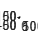

fis_full = addRule(fis_full,rules);
figure(6); gensurf(fis_full)

writeFIS(fis_full,fis_full.Name)

## Create control theory like Sugeno FISes

This approach generates 2 fuzzy inference systems. The first will generate a reference velocity trajectory dependent on the altitude of the vehicle. The second FIS computes the required thrust dependent on the control error. The control error is the difference between reference velocity and current velocity of the spacecraft:


$$e = v_{ref} - v
$$


Both velocity variables are negative. If e.g. v_ref = -80 and v = -100, e=+20 and thrust should be higher to decrease speed. 

### FIS for generating reference velocity dependend on altitude

% create fis for reference velocity:
fis_refspeed = sugfis("Name","refspeed");
fis_refspeed = addInput(fis_refspeed,[0 1e4],"Name","altitude");
fis_refspeed = addOutput(fis_refspeed,[-120, 0],"Name","ref_vel");
% input membership functions:
fis_refspeed = addMF(fis_refspeed,"altitude","trimf",[-300, 0, 300],"Name","very low");
fis_refspeed = addMF(fis_refspeed,"altitude","trimf",[0, 1500, 3000],"Name","low");
fis_refspeed = addMF(fis_refspeed,"altitude","linsmf",[1500, 3000],"Name","high");
figure(3); plotmf(fis_refspeed,"input",1)

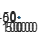

% output membership functions:
fis_refspeed = addMF(fis_refspeed,"ref_vel","constant",-100,"Name","fast");
fis_refspeed = addMF(fis_refspeed,"ref_vel","constant",-20,"Name","moderate");
fis_refspeed = addMF(fis_refspeed,"ref_vel","constant",-1,"Name","slow");
% rules:
% Column 1 — Index of membership function for first input
% Column 2 — Index of membership function for output
% Column 3 — Rule weight (from 0 to 1)
% Column 4 — Fuzzy operator (1 for AND, 2 for OR)
rules_refspeed = [ ...
    1, 3, 1, 1; ... % if altitude==very low => ref_vel=slow
    2, 2, 1, 1; ... % if altitude==low => ref_vel=moderate
    3, 1, 1, 1];    % if altitude==high => ref_vel=fast
fis_refspeed = addRule(fis_refspeed,rules_refspeed);
figure(4); gensurf(fis_refspeed)

writeFIS(fis_refspeed,fis_refspeed.Name)

### FIS for generating thust from control error

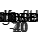

% create fis for reference velocity:
fis_thrust = sugfis("Name","thrust");
fis_thrust = addInput(fis_thrust,[-50,50],"Name","vel_err");
fis_thrust = addOutput(fis_thrust,[0,100],"Name","thrust");
% input membership functions:
fis_thrust = addMF(fis_thrust,"vel_err","linzmf",[-20,-10],"Name","much slower");
fis_thrust = addMF(fis_thrust,"vel_err","trimf",[-20,-10,0],"Name","slower");
fis_thrust = addMF(fis_thrust,"vel_err","trimf",[-5,0,5],"Name","good");
fis_thrust = addMF(fis_thrust,"vel_err","trimf",[0,10,20],"Name","fast");
fis_thrust = addMF(fis_thrust,"vel_err","linsmf",[10,20],"Name","much faster");
figure(5); plotmf(fis_thrust,"input",1)

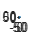

% output membership functions:
fis_thrust = addMF(fis_thrust,"thrust","constant",0 ,"Name","off");
fis_thrust = addMF(fis_thrust,"thrust","constant",20 ,"Name","low");
fis_thrust = addMF(fis_thrust,"thrust","constant",30 ,"Name","medium");
fis_thrust = addMF(fis_thrust,"thrust","constant",50 ,"Name","high");
fis_thrust = addMF(fis_thrust,"thrust","constant",100 ,"Name","maximum");
rules_thrust = [ ...
    1, 1, 1, 1; ... % if vel_error==much slower => thrust=off
    2, 2, 1, 1; ... % if vel_error==slower => thrust=low
    3, 3, 1, 1; ... % if vel_error==good => thrust=medium
    4, 4, 1, 1; ... % if vel_error==faster => thrust=high
    5, 5, 1, 1];    % if vel_error==much faster => thrust=maximum
fis_thrust = addRule(fis_thrust,rules_thrust);
figure(6); gensurf(fis_thrust)

writeFIS(fis_thrust,fis_thrust.Name)
